## Part 2: Modeling 

### Exercise 2.1

Given the rigid body diagram, derive the dynamic equation of the drone 

clear all; clc;

m = 0.5;                    %(kg)
M = diag([m,m,m])           %(kg)

M =     0.5000         0         0
         0    0.5000         0
         0         0    0.5000


L = 0.225;                  %(m)
k = 0.01;                   %(N s^2/rad^2)
b = 0.001;                  %(Nm s^2/rad^2)
D = diag([0.01,0.01,0.01]); %Represent the drag 
Iyy = 3*exp(-6);            %Moments of inertia on y axis (Nm s^2/rad)
Ixx = Iyy;                  %Moments of inertia on x axis (Nm s^2/rad)
Izz = exp(-5);              %Moments of inertia on z axis (Nm s^2/rad)
I = diag([Ixx, Iyy, Izz]);
g = [0;0;-9.81];            % gravitational acceleration (m/s^2)

p0      = transpose([0, 0, 0]); %x, y, z
p_dot0  = transpose([0, 0, 0]); % velocities
Omega0      = transpose([0, 0, 0]); % Rotation
Omega_dot0  = transpose([0, 0, 0]); % Angular velocity

%Ohm     = transpose([0, 0, 0, 0]);
%Ohm     = transpose([10000, 0, 10000, 0]);
Ohm     = transpose([0, 10000, 0, 10000]);
%Ohm     = transpose([10000, 10000, 10000, 10000]);

#### Exercise 2.1.1

Define the rotation matrix representing the orientation of the body-fixed frame w.r.t. the inertial frame. 

phi = Omega0(1);    % Get these values from the rotation
theta = Omega0(2);
psi = Omega0(3);

R = [cos(psi)*cos(theta), -sin(psi)*cos(phi) + cos(psi)*sin(theta)*sin(phi), sin(psi)*sin(phi) + cos(psi)*sin(theta)*cos(phi);
     sin(psi)*cos(theta), cos(psi)*cos(phi) + sin(psi)*sin(theta)*sin(phi), -cos(psi)*sin(phi) + sin(psi)*sin(theta)*cos(phi);
     -sin(theta), cos(theta)*sin(phi), cos(theta)*cos(phi)
    ]

R =      1     0     0
     0     1     0
     0     0     1


#### Exercise 2.1.2

Define the relation between the angular velocity dot(Θ) and the rotational velocity of the bodyfixed frame ω. 

rot =  [1, 0, -sin(theta);
        0, cos(phi), cos(theta)*sin(phi);
        0, -sin(phi), cos(theta)*cos(phi)
       ]

rot =      1     0     0
     0     1     0
     0     0     1


#### Exercise 2.1.3

Write the linear and angular dynamic equation of the drone in compact form, and clearly show each component of the equation explicitly

%Linear equation
%Propeller Thrust and viscous dampning
FB = k*[0; 0; sum(Ohm.^2)]; 
%linear dynamic acceleration
p_dot_dot = g+(1/m*R*FB) 

p_dot_dot = 	1.0e+06 *

         0
         0
    4.0000



%Total body torque
tau_B = [L*k*(Ohm(1)^2 - Ohm(3)^2); L*k*(Ohm(2)^2 - Ohm(4)^2); b*(Ohm(1)^2 - Ohm(2)^2 + Ohm(3)^2 - Ohm(4)^2)];
%Angular dynamic equation 
Omega_dot = inv(I)*(tau_B-cross(Omega0,(I*Omega_dot0)))

Omega_dot = 	1.0e+07 *

         0
         0
   -2.9683


#### Exercise 2.1.4 

Make a MATLAB/Simulink model of the drone, given initial conditions p(0) = [0, 0, 0]T , p˙(0)= [0, 0, 0]T , Θ(0) = [0, 0, 0]T and Θ(0) = [0 ˙ , 0, 0]T , and report the following:

    • Make a plot of p and Θ, given Ω = [0, 0, 0, 0]T and explain the result 

    • Make a plot of p and Θ, given Ω = [10000, 0, 10000, 0]T and explain the result 

    • Make a plot of p and Θ, given Ω = [0, 10000, 0, 10000]T and explain the result

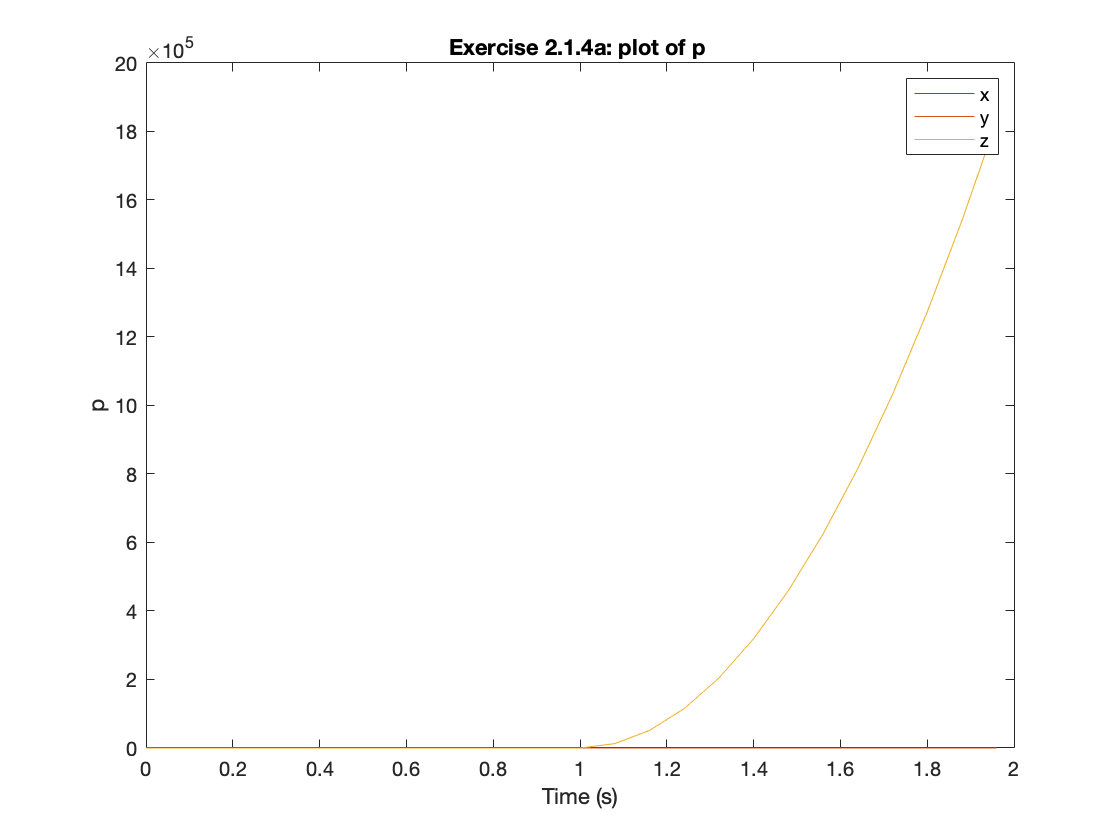

%When Omega = 0,0,0,0

out = sim('Ex21');
p_sim = get(out, "p_sim");
omega_sim = get(out,"Theta_sim");
%sim.p_sim
plot(p_sim)
title('Exercise 2.1.4a: plot of p ')
hold on 
xlabel("Time (s)")
ylabel("p")
legend('x','y', 'z')
hold off

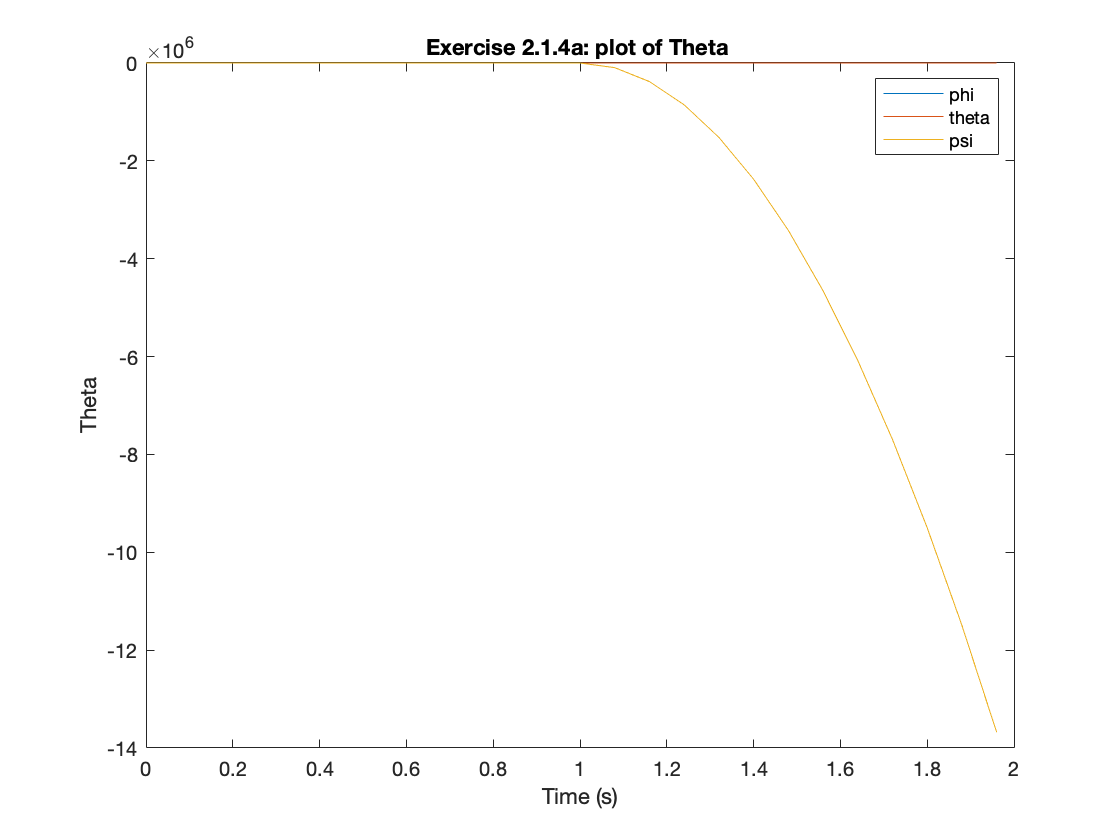


plot(omega_sim)
title('Exercise 2.1.4a: plot of Theta ')
hold on 
xlabel("Time (s)")
ylabel("Theta")
legend('phi','theta', 'psi')
hold off

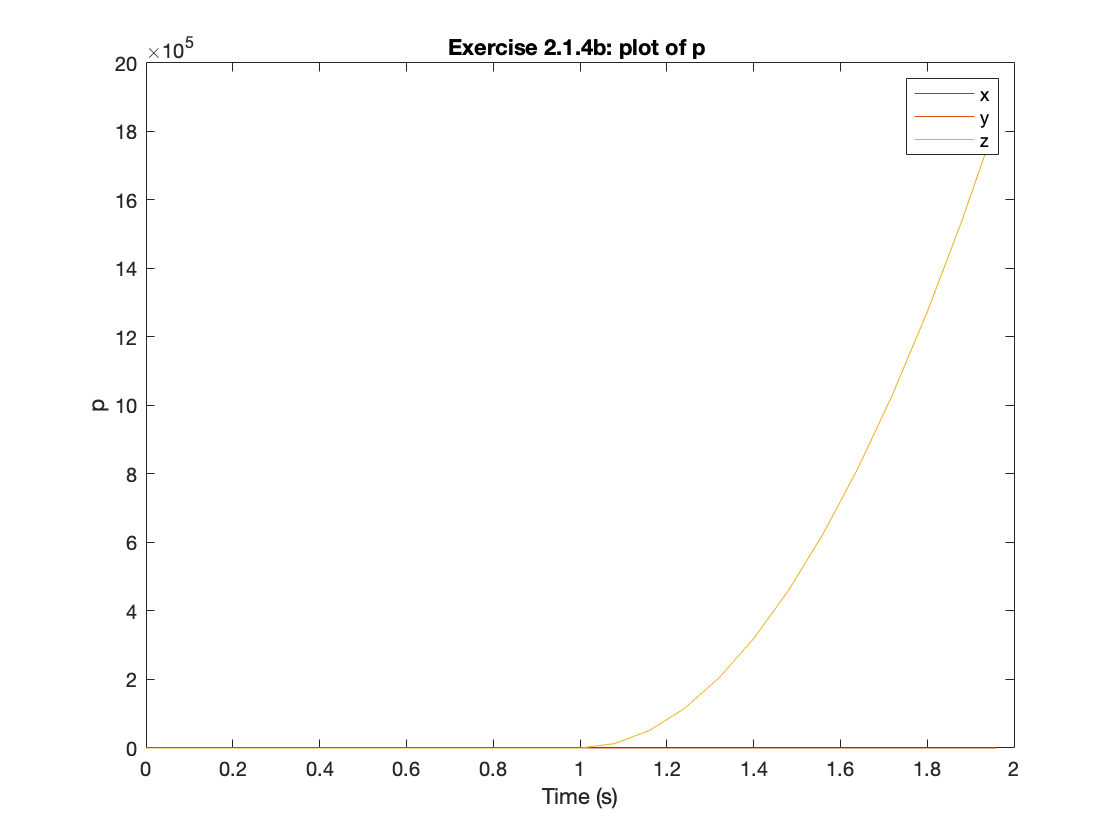

%When omega = 10000, 0, 10000, 0

out = sim('Ex21');
p_sim = get(out, "p_sim");
omega_sim = get(out,"Theta_sim");
%sim.p_sim
plot(p_sim)
title('Exercise 2.1.4b: plot of p ')
hold on 
xlabel("Time (s)")
ylabel("p")
legend('x','y', 'z')
hold off

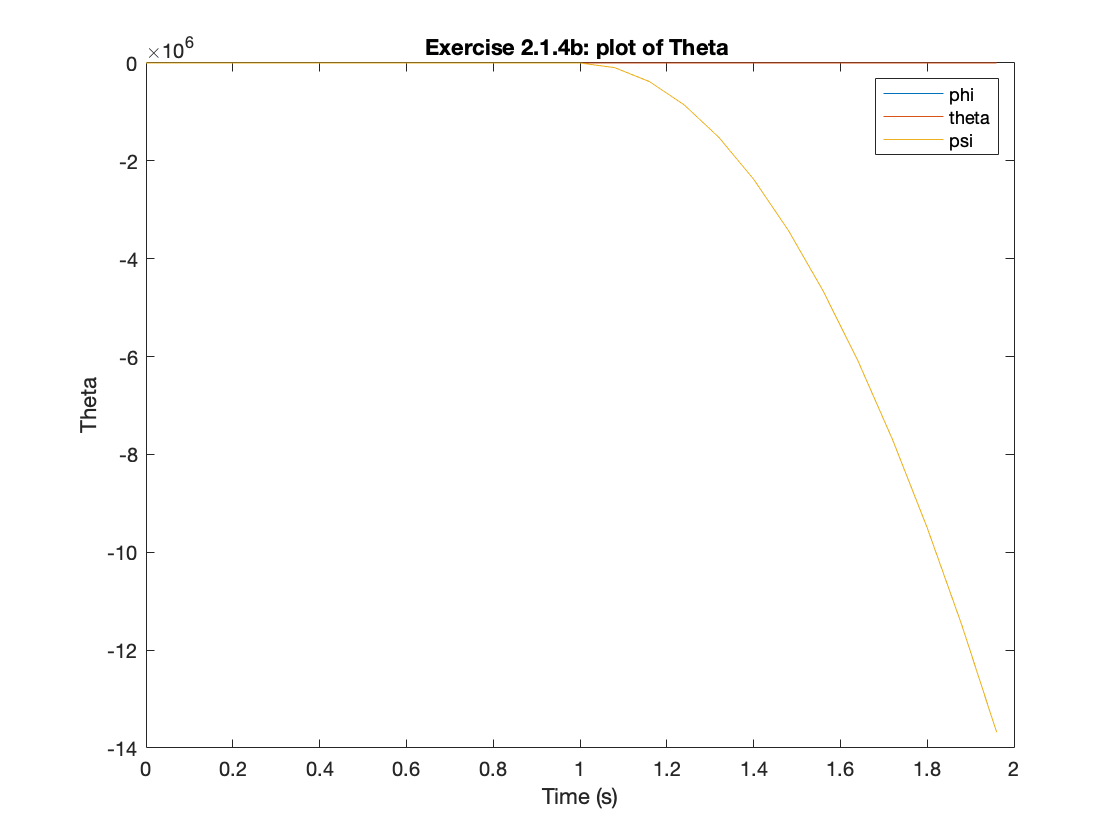


plot(omega_sim)
title('Exercise 2.1.4b: plot of Theta ')
hold on 
xlabel("Time (s)")
ylabel("Theta")
legend('phi','theta', 'psi')
hold off

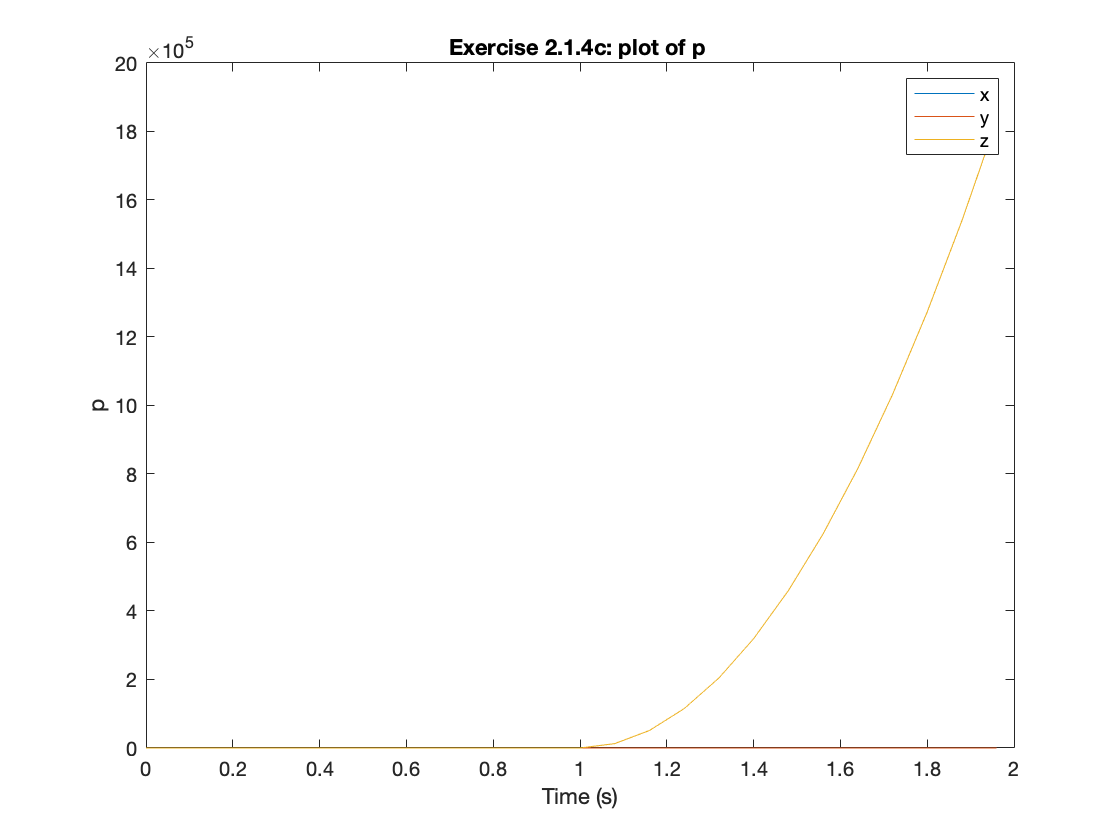

%When omega = 0, 10000, 0, 10000

out = sim('Ex21');
p_sim = get(out, "p_sim");
omega_sim = get(out,"Theta_sim");
%sim.p_sim
plot(p_sim)
title('Exercise 2.1.4c: plot of p ')
hold on 
xlabel("Time (s)")
ylabel("p")
legend('x','y', 'z')
hold off

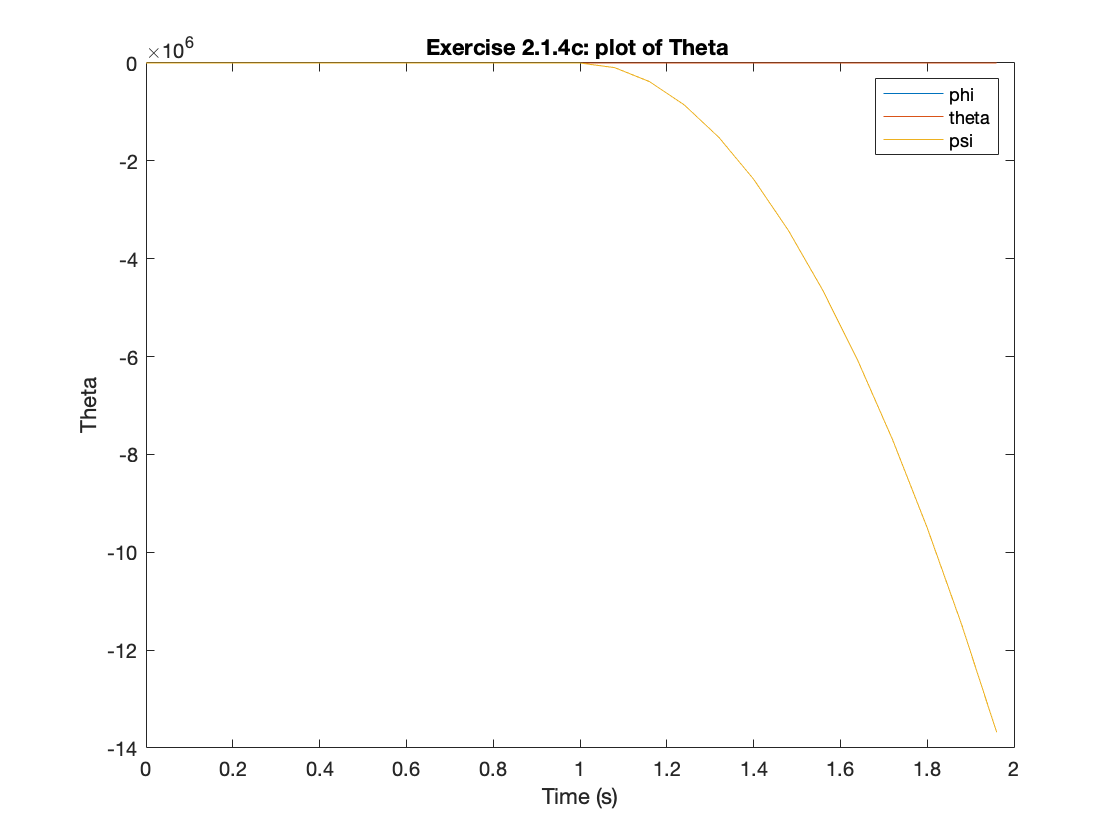


plot(omega_sim)
title('Exercise 2.1.4c: plot of Theta ')
hold on 
xlabel("Time (s)")
ylabel("Theta")
legend('phi','theta', 'psi')
hold off